Testing file: task1_1.mat


Absolute RMSE for task1_1.mat: 3962.4472 m


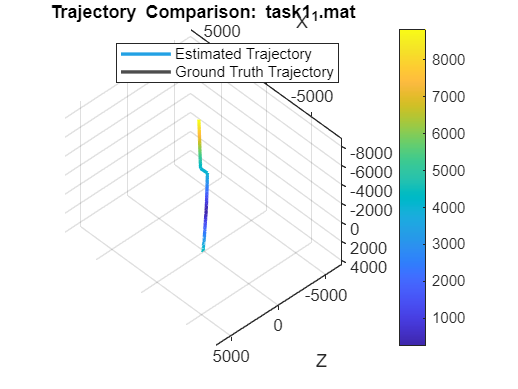

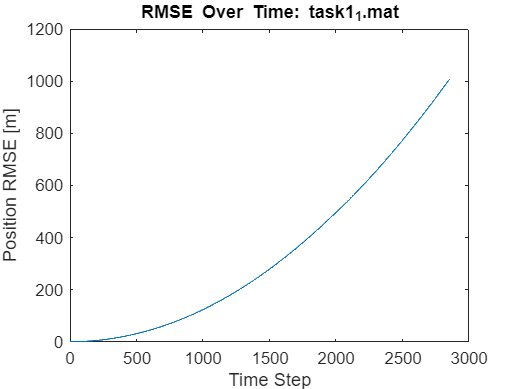

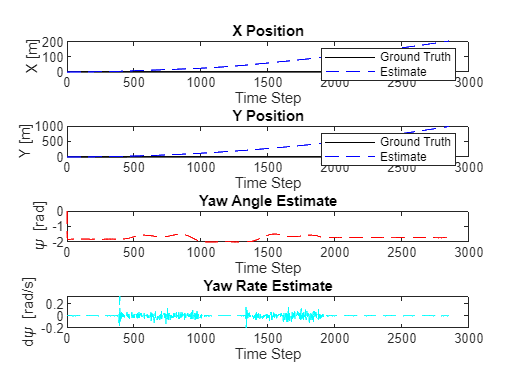

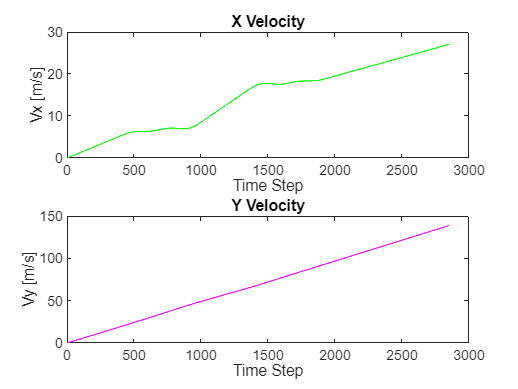

% Test all task datasets using your EKF function with evaluation and visualisation

taskFiles = {
    'task1_1.mat'%, 'task1_2.mat', 'task1_3.mat', 'task1_4.mat', ...
    %'task2_1.mat', 'task2_2.mat', 'task2_3.mat', 'task2_4.mat'
};

for k = 1:length(taskFiles)
    fprintf('\n==============================\n');
    fprintf('Testing file: %s\n', taskFiles{k});
    fprintf('==============================\n');

    try
        % Load the task file
        load(taskFiles{k}, 'out');

        % Call your EKF implementation
        [X_Est, P_Est, GT] = myEKF(out);

        % Convert ground truth to rigidtform3d
        pos = GT(:,1:3);
        N = size(pos,1);
        gtTforms(N) = rigidtform3d;
        for i = 1:N
            tGT = pos(i,:);
            RGT = eye(3);
            gtTforms(i) = rigidtform3d(RGT, tGT);
        end

        % Convert estimated states to rigidtform3d
        estTforms(N) = rigidtform3d;
        for i = 1:N
            tEst = [X_Est(i,1), X_Est(i,2), 0];
            R = eye(3);
            estTforms(i) = rigidtform3d(R, tEst);
        end

        % Compare trajectories
        metrics = compareTrajectories(estTforms, gtTforms, 'AlignmentType', 'rigid');
        fprintf('Absolute RMSE for %s: %.4f m\n', taskFiles{k}, metrics.AbsoluteRMSE(2));
        figure;
        plot(metrics, 'absolute-translation');
        title(['Trajectory Comparison: ', taskFiles{k}]);

        % RMSE over time
        positionErrors = sqrt(sum((X_Est(:,1:2) - GT(:,1:2)).^2, 2));
        figure;
        plot(1:N, positionErrors);
        title(['RMSE Over Time: ', taskFiles{k}]);
        xlabel('Time Step'); ylabel('Position RMSE [m]');

        % Visualisation of all states
        figure;
        subplot(4,1,1);
        plot(1:N, GT(:,1), 'k-', 1:N, X_Est(:,1), 'b--');
        title('X Position'); legend('Ground Truth','Estimate'); xlabel('Time Step'); ylabel('X [m]');

        subplot(4,1,2);
        plot(1:N, GT(:,2), 'k-', 1:N, X_Est(:,2), 'b--');
        title('Y Position'); legend('Ground Truth','Estimate'); xlabel('Time Step'); ylabel('Y [m]');

        subplot(4,1,3);
        plot(1:N, X_Est(:,5), 'r--');
        title('Yaw Angle Estimate'); xlabel('Time Step'); ylabel('\psi [rad]');

        subplot(4,1,4);
        plot(1:N, X_Est(:,6), 'c--');
        title('Yaw Rate Estimate'); xlabel('Time Step'); ylabel('d\psi [rad/s]');

        % Velocity visualisation
        figure;
        subplot(2,1,1);
        plot(1:N, X_Est(:,3), 'g'); title('X Velocity'); xlabel('Time Step'); ylabel('Vx [m/s]');
        subplot(2,1,2);
        plot(1:N, X_Est(:,4), 'm'); title('Y Velocity'); xlabel('Time Step'); ylabel('Vy [m/s]');

        % ToF visualisation (last 3 states assumed to be ToF estimates)
        if size(X_Est,2) >= 9
            figure;
            plot(1:N, X_Est(:,7), 'b', 1:N, X_Est(:,8), 'g', 1:N, X_Est(:,9), 'r');
            title('ToF Distance Estimates'); xlabel('Time Step'); ylabel('Distance [m]');
            legend('ToF1','ToF2','ToF3');
        end

    catch ME
        warning('Failed to process %s: %s', taskFiles{k}, ME.message);
    end
end

size(out.Sensor_ACCEL.signals.values)

ans =            1           3        2854
